# b. ODEs

write ode based on the flow charts

# c. initial value

time=0

[I]=1, [A]=0, [AP]=0, [IK]=0

k=10;
kIcat=10;
kAcat=100;
Ptot=1;
Ktot=1;

fa =@(a,i,ap,ik) -k*(Ptot-ap)*a+k*ap+kAcat*ik; 
fap =@(a,i,ap,ik) k*(Ptot-ap)*a-k*ap-kIcat*ap;
fi =@(a,i,ap,ik) -k*(Ktot-ik)*i+k*ik+kIcat*ap;
fik =@(a,i,ap,ik) k*(Ktot-ik)*i-k*ik-kAcat*ik;

dxdt = @(t,x)[fa(x(1),x(2),x(3),x(4));
              fap(x(1),x(2),x(3),x(4));
              fi(x(1),x(2),x(3),x(4));
              fik(x(1),x(2),x(3),x(4))];

[T, X] = ode45(dxdt, [0,2], [0.0,1.0,0.0,0.0]);

figure; hold on;
plot(T,X(:,1),'-r'); % A
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % I
plot(T,X(:,3),'-', 'color', [0 0 1]); % AP
plot(T,X(:,4),'-', 'color', [0.5 0]); %IK
ylabel('Molecular concentration (micromolar)')
xlabel('Time (hours)')

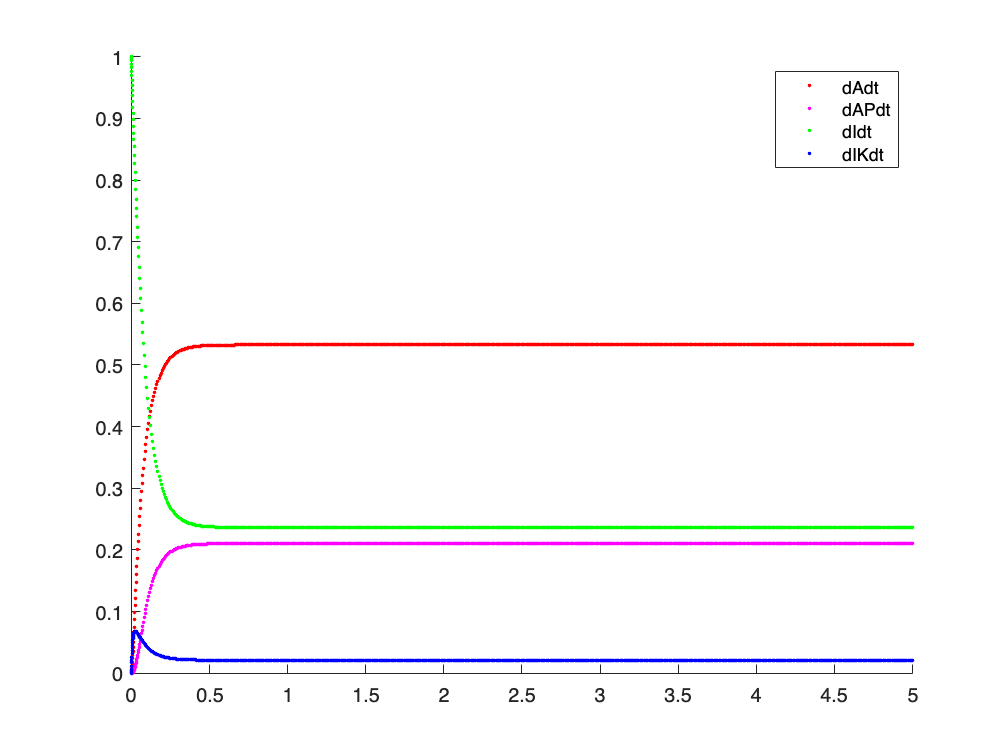



%initial conditions
clear all
close all

Ainit=0; %unbound active
Iinit=1; %unbound inactive
APinit=0; %complex
IKinit=0; %complex


kAon = 10 ;
kAoff = 10;
kIon = 10;
kIoff = 10;
kIcat = 10;
kAcat = 100;

Ptot=1;
Ktot=1;

dAdt =@(A, AP, I, IK) -kAon*(Ptot-AP)*A + kAoff*AP + kAcat*IK; 
dAPdt =@(A, AP, I, IK) kAon*(Ptot-AP)*A - kAoff*AP - kIcat*AP;
dIdt =@(A, AP, I, IK) -kIon*(Ktot-IK)*I + kIoff*IK + kIcat*AP;
dIKdt =@(A, AP, I, IK) kIon*(Ktot-IK)*I - kIoff*IK - kAcat*IK;
dxdt = @(t,x)[dAdt(x(1),x(2), x(3), x(4));
              dAPdt(x(1),x(2), x(3), x(4))
              dIdt(x(1),x(2), x(3), x(4))
              dIKdt(x(1),x(2), x(3), x(4))];

[T, X] = ode45(dxdt, [0,5], [Ainit, APinit, Iinit, IKinit] );
hold on
plot(T, X(:,1), 'r.')
plot(T, X(:,2), 'm.')
plot(T, X(:,3), 'g.')
plot(T, X(:,4), 'b.')

legend('dAdt','dAPdt','dIdt','dIKdt')
hold off


%% 
clear;

Ainit=0; %unbound active
Iinit=100; %unbound inactive
APinit=0; %complex
IKinit=0; %complex


kAon = 10 ;
kAoff = 10;
kIon = 10;
kIoff = 10;
kIcat = 10;
kAcat = 100;

Ptot=1;

n=100;
A=zeros(n,1);
Ktotlist=logspace(-3,2,n);

for i=1:n

Ktot=Ktotlist(i);
dAdt =@(A, AP, I, IK) -kAon*(Ptot-AP)*A + kAoff*AP + kAcat*IK; 
dAPdt =@(A, AP, I, IK) kAon*(Ptot-AP)*A - kAoff*AP - kIcat*AP;
dIdt =@(A, AP, I, IK) -kIon*(Ktot-IK)*I + kIoff*IK + kIcat*AP;
dIKdt =@(A, AP, I, IK) kIon*(Ktot-IK)*I - kIoff*IK - kAcat*IK;

dxdt = @(t,x)[dAdt(x(1),x(2), x(3), x(4));
              dAPdt(x(1),x(2), x(3), x(4))
              dIdt(x(1),x(2), x(3), x(4))
              dIKdt(x(1),x(2), x(3), x(4))];

[T, X] = ode45(dxdt, [0,5], [Ainit, APinit, Iinit, IKinit] );
A(i,1)=X(end,1);
end

plot(Ktotlist,A)
xlabel("Ktotal")
ylabel("total amount of actived protein")
%set(gca, 'XScale', 'log') %switch to x scale to log


if we change the initial value for I from 1 to 100, steady state will change from 0.7 to 100

why?

ultrasensitivity

pros: swith-like changes protein

cons: high sensitivity for noise and fluctuation